- Fent us SUM

1+2+...+n Vn

n = 10

n = 10

%n = input('entra valor n = ')
sum(1:n)

ans = 55

1+2^p+....+n^p   Vn, Vp

n = 2

n = 2

p = 10

p = 10

%n = input('entra valor n = ')
%p = input('entra valor p = ')
sum((1:n).^p) 

ans = 1025

resultat = ejercicio5(5)

resultat =           2.41699868665013


resultat = ejercicio6(20)

g = function_handle with value:
    @(x)x.^2./(sqrt(x.^2+1)+1)


resultat =                          0                         1         0.414213562373095         0.414213562373095
                         1                     0.125       0.00778221853731864       0.00778221853731871
                         2                  0.015625      0.000122062862828676      0.000122062862828759
                         3               0.001953125       1.9073468138231e-06      1.90734681382657e-06
                         4            0.000244140625      2.98023219436061e-08      2.98023219436061e-08
                         5          3.0517578125e-05      4.65661287307739e-10      4.65661287199319e-10
                         6        3.814697265625e-06      7.27595761418343e-12      7.27595761415696e-12
                         7      4.76837158203125e-07      1.13686837721616e-13       1.1368683772161e-13
                         8      5.96046447753906e-08      1.77635683940025e-15      1.77635683940025e-15
                         9      7.4505805969

resultat = array2table(resultat, ...,
    'VariableNames',{'n','xn','f','g'})

resultat = 21×4 table
    n              xn                      f                       g          
    __    ____________________    ____________________    ____________________

     0                       1       0.414213562373095       0.414213562373095
     1                   0.125     0.00778221853731864     0.00778221853731871
     2                0.015625    0.000122062862828676    0.000122062862828759
     3             0.001953125     1.9073468138231e-06    1.90734681382657e-06
     4          0.000244140625    2.98023219436061e-08    2.98023219436061e-08
     5        3.0517578125e-05    4.65661287307739e-10    4.65661287199319e-10
     6      3.814697265625e-06    7.27595761418343e-12    7.27595761415696e-12
     7    4.76837158203125e-07    1.13686837721616e-13     1.1368683772161e-13
     8    5.96046447753906e-08    1.77635683940025e

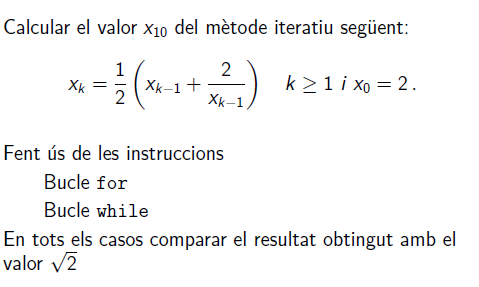

n = 10;
k = 2;
x(1) = 2;
while (k <=n && x(k-1) > 5e-14)
    x(k) = 0.5*(x(k-1)+(2/x(k-1)));
    k = k+1;
end
R = [1:length(x); x;abs(x-sqrt(2));abs(x-sqrt(2))/abs(sqrt(2))]'

R =                          1                         2         0.585786437626905         0.414213562373095
                         2                       1.5        0.0857864376269049        0.0606601717798212
                         3          1.41666666666667       0.00245310429357137       0.00173460668094215
                         4          1.41421568627451      2.12390141451912e-06      1.50182509277817e-06
                         5          1.41421356237469      1.59472435257157e-12      1.12764040382669e-12
                         6          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                         7          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                         8          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                         9          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                        10          1.4142135623730


n = 15;
x2(1) = 2;
for k = 2:1:n
    x2(k) = 0.5*(x2(k-1)+(2/x2(k-1))); 
    if x2(k) < 5e-14
       break
    end
end

R2 = [1:length(x2); x2;abs(x2-sqrt(2));abs(x2-sqrt(2))/abs(sqrt(2))]'

R2 =                          1                         2         0.585786437626905         0.414213562373095
                         2                       1.5        0.0857864376269049        0.0606601717798212
                         3          1.41666666666667       0.00245310429357137       0.00173460668094215
                         4          1.41421568627451      2.12390141451912e-06      1.50182509277817e-06
                         5          1.41421356237469      1.59472435257157e-12      1.12764040382669e-12
                         6          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                         7          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                         8          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                         9          1.41421356237309      2.22044604925031e-16      1.57009245868377e-16
                        10          1.414213562373

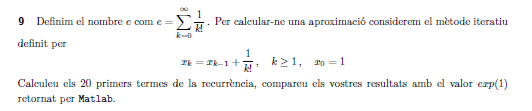

x(1) = 1;
p = 1;
k = 1;
nmax = 20;
tol(k) = abs(x(k)-exp(1))

tol =           1.71828182845905         0.718281828459046         0.218281828459046         0.051615161792379        0.0099484951257125       0.00161516179237919      0.000226272903490088      2.78602050771681e-05      3.05861777549765e-06      3.02885853287194e-07      2.73126610217389e-08      2.26055263397029e-09      1.72876823967272e-10      1.22861720797118e-11      8.15347789284715e-13      5.06261699229071e-14      2.66453525910038e-15                         0


while(tol(k) > eps) && (k<nmax)
    p = p*k;
    k = k+1;
    x(k) = x(k-1) +1/p;
    tol(k) = abs(x(k)-exp(1));
end
R = [1:length(x); x; tol]'

R =                          1                         1          1.71828182845905
                         2                         2         0.718281828459046
                         3                       2.5         0.218281828459046
                         4          2.66666666666667         0.051615161792379
                         5          2.70833333333333        0.0099484951257125
                         6          2.71666666666667       0.00161516179237919
                         7          2.71805555555556      0.000226272903490088
                         8          2.71825396825397      2.78602050771681e-05
                         9          2.71827876984127      3.05861777549765e-06
                        10          2.71828152557319      3.02885853287194e-07


Polinomis

x^3-3*x^2+3*x+3

= ((x-3)*x+3)x+3 -> Regla de Horner

p = [1 -3 3 3]

p =      1    -3     3     3


x = linspace(-5,5,200)

x =                         -5         -4.94974874371859         -4.89949748743719         -4.84924623115578         -4.79899497487437         -4.74874371859296         -4.69849246231156         -4.64824120603015         -4.59798994974874         -4.54773869346734         -4.49748743718593         -4.44723618090452         -4.39698492462312         -4.34673366834171          -4.2964824120603         -4.24623115577889         -4.19597989949749         -4.14572864321608         -4.09547738693467         -4.04522613065327         -3.99497487437186         -3.94472361809045         -3.89447236180905         -3.84422110552764         -3.79396984924623         -3.74371859296482         -3.69346733668342         -3.64321608040201          -3.5929648241206          -3.5427135678392         -3.49246231155779         -3.44221105527638         -3.39195979899498         -3.34170854271357         -3.29145728643216         -3.24120603015075         -3.19095477386935         -3.14070351758794        

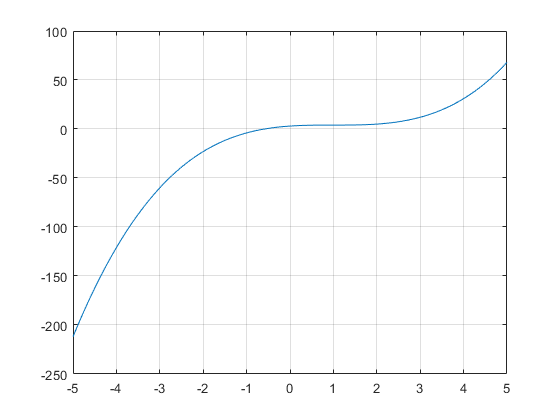

%%polyval utilitza horner
y = polyval(p,x);
plot(x,y)
grid

roots(p)

ans =             1.7937005259841 +       1.3747296369986i
            1.7937005259841 -       1.3747296369986i
         -0.587401051968199 +                     0i


# **Polinomi de Wilkinson**

roots(1:10)

ans =           -1.33859118589308 +                     0i
          -1.09704408762781 +     0.756988433625517i
          -1.09704408762781 -     0.756988433625517i
         -0.465689376213834 +      1.22950234299199i
         -0.465689376213834 -      1.22950234299199i
          0.310290909092414 +      1.24228190323516i
          0.310290909092414 -      1.24228190323516i
          0.921738147695767 +     0.796363824394796i
          0.921738147695767 -     0.796363824394796i


p = poly(1:10)'

p =            1
         -55
        1320
      -18150
      157773
     -902055
     3416930
    -8409500
    12753576
   -10628640


q = p

q =            1
         -55
        1320
      -18150
      157773
     -902055
     3416930
    -8409500
    12753576
   -10628640


format long g
q(2)=q(2)+1/2^(13)

q =                          1
         -54.9998779296875
                      1320
                    -18150
                    157773
                   -902055
                   3416930
                  -8409500
                  12753576
                 -10628640


roots(q)

ans =            9.71680694440454 +     0.423492822039221i
           9.71680694440454 -     0.423492822039221i
           7.39701333900533 +     0.749263119716399i
           7.39701333900533 -     0.749263119716399i
           5.67612069756221 +                     0i
           5.10313498919566 +                     0i
           3.99274462886153 +                     0i
           3.00023859699748 +                     0i
           1.99999844991441 +                     0i
           1.00000000033645 +                     0i


# Equaciones lineales

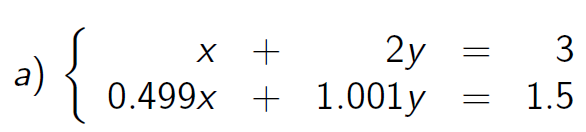

format short g
A = [1 2; 0.499  1.001]

A =             1            2
        0.499        1.001


B = [3;1.5]

B =             3
          1.5


SOL = A\B

SOL =             1
            1


det(A)

ans =         0.003

cond(A)

ans =        2083.7

function [resultat] = ejercicio5(m)
resultat = 1;
p = 1;
    for n = 0:1:m
         p = p * (-1/3);
         aux = p/(2*n+1);
         resultat = resultat + aux;
    end
resultat = resultat * sqrt(12);
end 

function [resultat] = ejercicio6(n)
k = 0:n;
x = 8.^(-k);
f = @(x)sqrt(x.^2+1)-1;
g = @(x)x.^2./(sqrt(x.^2+1)+1)
resultat = [k;x;f(x);g(x)]';
end